# ENGR105    ---    Problem Set 11    ---   Simulations

## Due: Wednesday, 11/25/2020

## Name:

#### The University of Pennsylvania code of academic integrity can be found here:

[https://catalog.upenn.edu/pennbook/code-of-academic-integrity/](https://catalog.upenn.edu/pennbook/code-of-academic-integrity/)

By submitting this assignment, you certify that you completed this assignment in compliance with the code of academic integrity, as defined above, and that the work here is your own. Collaboration is allowed and encouraged but  it is in your own best interest to be able to complete all the problems on your own. Collaboration is allowed, COPYING is NOT. Be sure you are able to reason through each step. 

#### Notes on HW submission:

- Please save the final document In the following format: "<your last name>_<your first name>_HW11.mlx

- Run the entire document (`f5`) prior to submitting. Following this, please **export to .pdf** and **submit both** the .mlx file and the .pdf file to Canvas.

- If it is not selected by default, select "Output Inline" at the top right of the LiveScript document to display the output below your code (rather than to the right).

#### Purpose of this problem set:

- Create a complex simulation and visualize the results

- Think about the real-world context and implications of the results

#### Notes about MATLAB LiveScripts:

- The gray regions are "code" regions. Entering and running your code here is the same as running it in a `.m` script file or on the command line.

- "Running a piece of code" means you are executing the code in that section only. **Press **`Cntl`** + **`Enter`** to run a given section.**

- Press `f5` to run all sections of the document.

- To remove inline figures, right click and select "Clear All Output."

- When you run a section (each section refers to a different problem or part of a problem), all variables and vectors are stored in MATLAB and may be called from the command line.

**Reminder: Prior to submitting, be sure to run ****all**** sections of the document to ensure that it works properly. After running all sections, export the document to pdf.**

## PROBLEM 1 (100 pts): The prisoner's dilemma revisited

In Homework #7, we discussed the prisoner's dilemma, a thought experiment in game theory that describes how two completely rational individuals might not cooperate, even if it appears that it is in their collective best interests to do so. In that problem, we simulated the **outcome of 250 interactions between two individuals**, where each interaction is *one instance of the prisoner's dilemma ***AND** *both individuals ****remember**** their prior interactions with the other individual*. Furthermore, each individual can approach the interactions in a different way*: *the `goodPerson` always chose to cooperate (regardless of previous interactions), the `badPerson` always chose to be hostile, the `arbitraryPerson` acted carelessly, and **you created a function that describes how you would approach these set of interactions**. Before starting this problem, please review problem 3 of Homework #7 to refresh your memory of this problem.

In this homework, we will simulate the group dynamics of a population whose "internal sets of interactions" are governed by the prisoner's dilemma in the exact same way as above and in Homework #7. **However, we are going to make this especially interesting**: the members of the population are going to act in accordance with the functions that **everyone in ENGR105 created for Homework #7**. A zip folder containing all of these functions (along with `goodPerson`, `badPerson`, `arbitraryPerson`, and `massiveRetaliation`) is provided with this homework. **Your goal: simulate the evolution of this "ENGR105 society**."

**a) Background.** **Important**: before starting, please listen to the following episode of **Radiolab**. **Please listen to the entire episode** -- it is less than 30 minutes. In this homework assignment we will be performing the same exact simulations that became famous in the 1960s.

[https://www.wnycstudios.org/podcasts/radiolab/segments/104010-one-good-deed-deserves-another](https://www.wnycstudios.org/podcasts/radiolab/segments/104010-one-good-deed-deserves-another)

**b) (20 points) Preparation**. Before jumping straight into simulations, the first step (Prepare, plan, pseudocode) is to import the prisoner dilemma functions and store them in a convenient format. The folder `HW11_individuals` contains** 54 functions**.** Import these into a cell array, such that each cell contains a ****function handle**** for one of the functions.**

%run through the folder
%change the name of the folder into a function handle 
files = dir("HW11_Subgroups")

files = 56×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


strategies = {};
for k = 3:size(files)
    strategies{k-2} = str2func(files(k).name(1:end-2)); 
end
strategies{3}

ans = function_handle with value:
    @goodPerson


size(strategies)

ans =      1    54


***Hints and potentially useful functions:***

- `str2func`: converts a character array (representing a built-in function or a function in the Current Folder) into a function handle.

- `contains`: returns a logical vector if a "pattern is found in text." This could be useful because it can operate on cell arrays.

- `dir`: lists the files in a folder

- Your text processing experience from Homework #8 might be useful.

***The first few entries in your cell array should be similar to the following:***

`  Columns 1 through 3`

`    {@arbitraryPerson}    {@badPerson}    {@goodPerson}`

`  Columns 4 through 6`

`    {@massiveRetaliation}    {@pd004595}    {@pd012013}`

**c) (20 points) Starting simple.** Before we simulate the evolution of the group, let's create a simple simulation that merely pits each player against another player in an instance of the prisoner's dilemma. Since there are 54 players, this code should simulate 27 matchups between different pairs of players.

**Details and notes:**

- Please check out and **use** the provided function, `prisonerDilemmaSim`, at the end of this LiveScript document. This is the exact same function as was used in Homework #7, **except** that it returns the two players' scores as outputs: the first output corresponds to the first player's score and the second output corresponds to the second player's score.

- Each player in this part should play the prisoner's dilemma exactly once. Thus, each matchup is between a different pair of players.

- The player that a given player plays against should be **chosen randomly** and should change every time this section is run.

**Note**: you should not change the code for `prisonerDilemmaSim` at any point of this homework.

**Produce a visualization depicting the scores of all players after this single round of simulations.** As always, your visualization should be clear and professional.

random = randperm(54)

random =     11    25    19    46     1    15    37    16    12    42    24     9    51    29    50    22    54    17     5    20    41    30    47    43    10    35    44    40    13    31    33    26    49    14    36    53     4     7     8    34    39    27    45    32     2    38    48     3    21    18


scores = zeros(1,54);
function_names = cell(1,54);

for k = 1:2:length(random)
    scores(1,k:k+1) = prisonerDilemmaSim(strategies{random(k)}, strategies{random(k+1)});
    function_names(:,k:k+1) = {func2str(strategies{random(k)}),func2str(strategies{random(k+1)})};

end
names = categorical(function_names)

names = 1×54 categorical array
     pd196790      pd541883      pd319162      pd844602      arbitraryPerson      pd30808116      pd691292      pd308321      pd198475      pd793245      pd51858926      pd075723      pd945983      pd576727      pd945573      pd350256      pd985662      pd308940      pd004595      pd322350      pd778551      pd58445958      pd863745      pd793431      pd096156      pd654321      pd816601      pd773708      pd207729      pd623853      pd625917      pd542405      pd89856909      pd232903      pd687051      pd965213      massiveRetaliation      pd021156      pd024116      pd632235      pd745463      pd56496420      pd82836888      pd624725      badPerson      pd694493      pd889454      goodPerson      pd340945      pd312490      pd37957805      pd964788      pd012013      pd57595151 



[orderedScore, I] = sort(scores,'descend');

orderedFunctionNames = function_names(I);

stratName = categorical(orderedFunctionNames);
stratName2 = reordercats(stratName, orderedFunctionNames)

stratName2 = 1×54 categorical array
     pd889454      goodPerson      pd012013      pd57595151      pd319162      pd844602      pd89856909      pd232903      massiveRetaliation      pd021156      pd024116      pd632235      pd37957805      pd964788      pd004595      pd322350      pd687051      pd965213      pd340945      pd312490      pd945983      pd576727      pd691292      pd308321      pd196790      pd541883      arbitraryPerson      pd30808116      pd198475      pd793245      pd82836888      pd624725      pd51858926      pd075723      pd745463      pd56496420      pd096156      pd654321      pd985662      pd308940      pd778551      pd58445958      pd625917      pd542405      badPerson      pd694493      pd945573      pd350256      pd816601      pd773708      pd863745      pd793431      pd207729      pd623853 


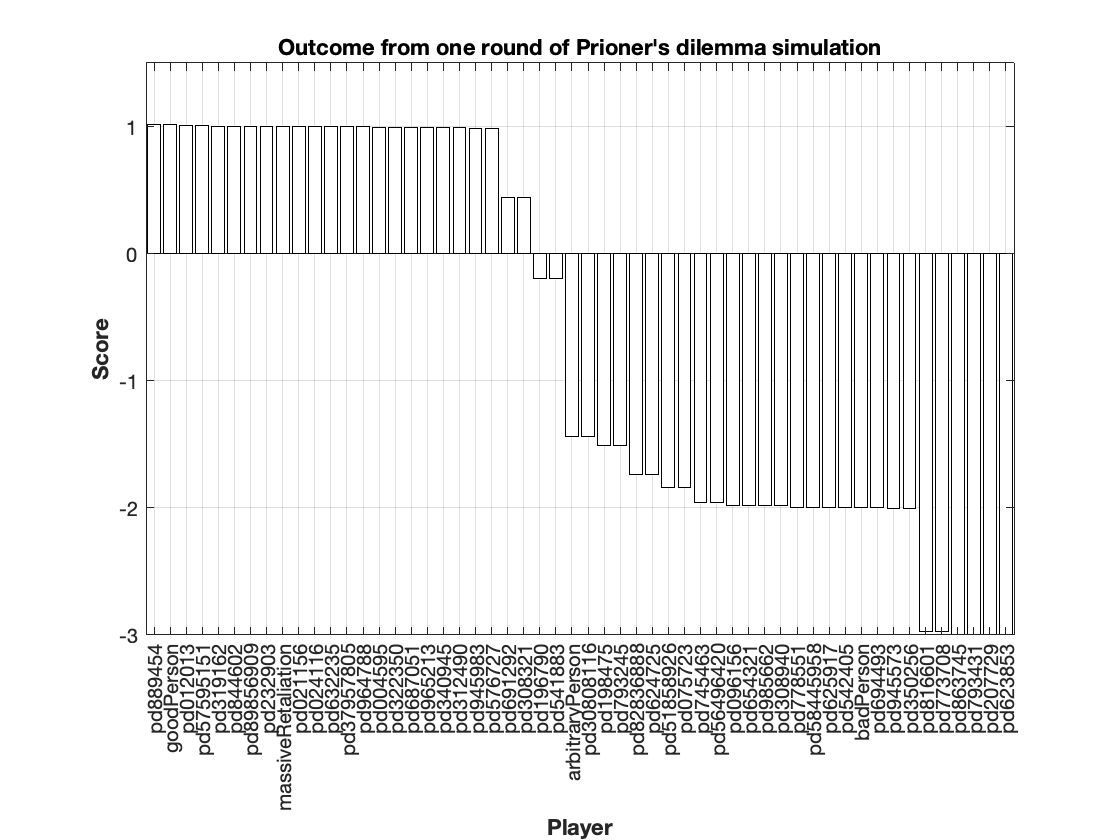


bar(stratName2, orderedScore, 'w');
title('Outcome from one round of Prioner''s dilemma simulation')
ylabel('Score', 'FontWeight', 'bold')
xlabel('Player', 'FontWeight', 'bold')
set(gca, 'XGrid', 'on', 'XTick', stratName2);
set(gca, 'YGrid', 'on', 'YTick', -4:1:4);

***Hints and tips:***

- `randperm` could be useful for "shuffling" player order.

- Your output plot should convey the same information as the following. The score for every individual should be listed.

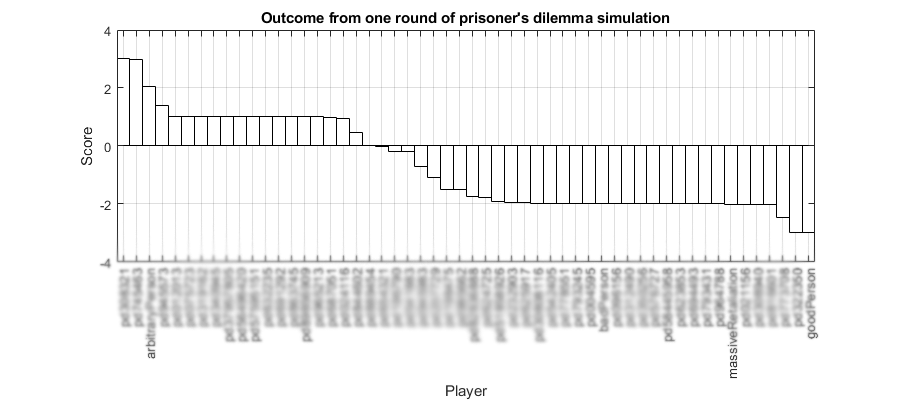

- Note that your simulation results may differ from that depicted above. I have intentionally blurred the names of the function handles to minimize confusion.

**d) (30 pts) Simulate the evolution of the group.** In the previous problems, we have organized and gained familiarity with our data set. Now, we are ready to take on the simulation that made **Robert Axelrod famous **in the early 1960s.

***Qualitative description of our simulation goal:***

Consider a group of individuals in a society. Each individual can interact with another individual (i.e. via the prisoner's dilemma, as before): if their interaction is cooperative, they both mildly succeed (e.g. gain resources, etc.); if one player is hostile and the other is cooperative, the hostile individual will "take advantage" of the other, and substantially gain resources; if both players are hostile the outcome will be disastrous for both. In this setting, some individuals will thrive and potentially prosper, while others may die off. **The purpose of this simulation is to determine how the composition of the group and the total group population changes over time.**

***Rules:***

- Create an **initial population** in which **five individuals approach the prisoner's dilemma for each function handle** defined above. That is, since there are 54 different approaches (function handles), the initial population should be **270** individuals.

- In a given simulation time step, each individual in the group interacts with another randomly chosen individual via the prisoner dilemma. That is, one simulation time step is analagous to what you created code for in part **c)**, except the total number of individuals will be different in each turn.

- Following each simulation time step, a running score for **each of the individuals** should be updated based on that most recent encounter of the prisoner's dilemma.

- **If, at the end of any time step, an individual's score drops below **`-2`, that individual** "dies"** and should be removed from the simulation.

- **If, at the end of any time step, an individual's score exceeds **`2`, that individual** reproduces a new copy of itself**. That is, the population will gain **one new individual** who approaches the prisoner's dilemma with the same approach (function handle) as the individual whose score exceeded 2.

- When this occurs, the score for both the **original individual** and the **newly spawned individual **should be **reset to zero**.

***Definitions:***

- Individual: one particular entity in the population. The individual should have a world view associated with **one** particular function handle.

- Subgroup: The collection of individuals associated with the same function handle. **Initially**, there are 54 active subgroups, with each containing five individuals.

- Group: The entire collection of individuals "alive" in the simulation.

- Extinct subgroup: a subgroup in which all individuals die out.

**Note**: you should not change the code for `prisonerDilemmaSim` at any point of this homework.

As a result of your simulation code, you should be able to access the number of individuals in each subgroup change over time. You will produce visualizations based on your code in parts **e)** and **f)**. Simulate **at least 10 simulation time steps. As always, ensure your code is clear, correct, and computationally efficient.**

random = randperm(270)

random =    209   257     3   230    51   217    53    97    31    37   178   103   192    18   182    68   117   116   171    22   184   143   196   265   134   262    27   197    63   133    87    66     5   125     9   186   232   129     8   238   162    40   146   246   225   223   147   118    92    56


scores = zeros(1,270);
function_names = cell(1,270);
groupIndividuals = ones(1,54)*5;
groupIndividualsCH = ones(1,54)*5;
groupIndividualsNorm = ones(1,54)*5/270;

individuals = [strategies, strategies, strategies, strategies, strategies];
numInd = 270;
originalFunctions = cell(1,54);

for k = 1:length(strategies)
    originalFunctions{k} = func2str(strategies{k});
end

for time_step = 1:10
    for k = 1:2:length(random)
        scores(1,k:k+1) = prisonerDilemmaSim(individuals{random(k)}, individuals{random(k+1)});
        function_names(:,k:k+1) = {func2str(individuals{random(k)}),func2str(individuals{random(k+1)})};
    
    end
    
    %do the thing to chack if it is less than 2 and to remove that position
    indexBelowNeg2 = ((1:length(scores)).*(scores<-2));
    indexBelowNeg2 = indexBelowNeg2(indexBelowNeg2~=0);
    
    %when the are below -2 remove the index
    %take the original functions and use this to 
    for k = 1:length(indexBelowNeg2)
        index = (string(originalFunctions)) == func2str(individuals{indexBelowNeg2(k)});
        index = (1:length(originalFunctions)).*index;
        groupIndividuals(index(index~=0)) = groupIndividuals(index(index~=0))-1;
    end
    
    
    %find the indices of where the score is greater than 2 
    indexAbove2 = ((1:length(function_names)).*(scores>2));
    indexAbove2 = indexAbove2(indexAbove2~=0);
    
    %find the positions of where you had more than 2 and then add one more
    %of that function
    for k = 1:length(indexAbove2)
        index = (string(originalFunctions)) == func2str(individuals{indexAbove2(k)});
        index = (1:length(originalFunctions)).*index;
        groupIndividuals(index(index~=0)) = groupIndividuals(index(index~=0))+1;
    end
    %delete if the score is less than negative 2
    
    individuals = [individuals, individuals(indexAbove2)];
    
    %reset the scores back to 0 if they are new or made a new one 
    scores(indexAbove2) = 0;
    scores(end:end+length(indexAbove2)) = 0;
    
    %matrix that keeps track of the change
    groupIndividualsCH = [groupIndividualsCH; groupIndividuals];
    
    %normalize it
    groupIndividualsCH = [groupIndividualsCH; groupIndividuals];
    
    %get the number of individuals 
    numInd = [numInd, length(individuals)];
    
    %adjust the amount for random based on how many individuvals left
    random = randperm(length(individuals));
    
end 

[orderedScore, I] = sort(scores,'descend');

orderedFunctionNames = function_names(I);

Index exceeds the number of array elements (390).


stratName = categorical(orderedFunctionNames);
stratName2 = reordercats(stratName, orderedFunctionNames)

bar(stratName2, orderedScore, 'stacked');

























**e) (10 pts) Visualizing the evolution.** Create a visualization that depicts both how the **entire group population** changes over time and how **individual subgroups** change over time. Subgroups that are thriving should be highlighted in some way.

**In case it is helpful:** I am visualizing the results from my simulation as follows, where the top graph depicts the proportion of each subgroup through time. You can depict your this way or another way, just make sure the above requirements are met. 

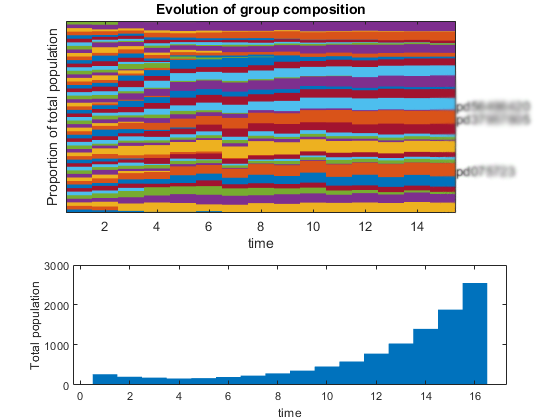

**Note**: the results from your simulations may be different than mine. I am intentionally blurring out the names of the high performing function handles.

**f) (10 pts) Visualizing the final state.** Produce a visualization or graphic that quantitatively depicts the composition of the group at the final state of your simulation. The **number of individuals in each subgroup** should be listed or represented and you should also list function handles associated with **extinct subgroups**.

**g) (10 pts) Your commentary.** Do your simulations results agree with Robert Axelrod's simulations, as described in the podcast in part **a)**? You may or may not observe that "strict tit-for-tat" performs the best. **In no more than 4-6 sentences, comment on your simulation and the results.**

*Your response:*

## Problem Set 11: functions stored below

function [p1_score,p2_score] = prisonerDilemmaSim(player1,player2)
    % This function plays the prisoners dilemma between player 1 and player
    % 2. Specifically it describes the outcome from 250 "player
    % iteractions," where the manner in which one player responds to the
    % other depends upon their "history." That is, if one player is a
    % "jerk," the other player will realize that as more and more
    % interactions occur.
    % 
    % NOTE 1. The inputs to this function are two function handles. One describing
    % how player 1 will "play." The second describing how player 2 will
    % "play."
    % 
    % NOTE 2. The options for "how" a player will respond are as follows: 
    % If a player wishes to cooperate:  the player's function will output 1
    % If a player wishes to be hostile: the player's function will output 0
    % 
    % NOTE 3. After each interaction, each player's "score" will be updated
    % depending on how well from them that interaction went. A high score
    % corresponds to a successful outcome for that player
    % 
    % NOTE 4. The rules for the interactions are as follows:
    % A) If both players cooperate (both output 1)
    %       Player 1's score: increase by 1
    %       Player 2's score: increase by 1
    % B) If both players are hostile (both output 0)
    %       Player 1's score: decrease by 2
    %       Player 2's score: decrease by 2
    % C) If player 1 cooperates but player 2 is hostile
    %    (Player 1 outputs 1, player 2 outputs 0)
    %       Player 1's score: decrease by 3
    %       Player 2's score: increase by 3
    % D) If player 1 is hostile but player 2 cooperates
    %    (Player 1 outputs 0, player 2 outputs 1)
    %       Player 1's score: increase by 3
    %       Player 2's score: decrease by 3
    
    
    % Variable storing number of interactions to consider. Here, we will
    % consider 250 turns.
    numTurns = 250;
    
    % Preallocate vector to store the output from each turn
    % Note: we will preallocate as NaN to avoid confusion because each
    % entry (corresponding to an interaction) will be either 0 or 1.
    p1_hist = nan(1,numTurns);
    p2_hist = nan(1,numTurns);

    % Stores the score of each player
    p1_score = 0;
    p2_score = 0;
    
    % Each successive iteration of this FOR loop corresponds to another
    % interaction between players
    for k = 1:numTurns
            
        % Determine how each player will play in the k-th interaction
        % Note: the output values will either be 0 or 1, corresponding to
        % NOTE 2, above
        % FIRST INPUT (in each): is THAT player's previous moves
        % SECOND INPUT (in each): is the OTHER player's previous moves
        out1 = player1(p1_hist(~isnan(p1_hist)),p2_hist(~isnan(p2_hist)));
        out2 = player2(p2_hist(~isnan(p2_hist)),p1_hist(~isnan(p1_hist)));

        % Update player 1 score based on NOTE 4
        p1_score = p1_score - 3 + 6*(out1<out2) + ...
            (out2==out1)*(4*(out1==1) + (out1==0));
        
        % Update player 2 score based on NOTE 4
        p2_score = p2_score - 3 + 6*(out1>out2) + ...
            (out2==out1)*(4*(out2==1) + (out2==0));

        % Store current action in vector containing histories of each
        % player's moves
        p1_hist(k) = out1;
        p2_hist(k) = out2;

    end
    
    % Normalize score by number of turns
    p1_score = p1_score/numTurns;
    p2_score = p2_score/numTurns;
end